# CA2 - SVD

In this assignment we explore the use of the singular value decomposition (SVD). The data you work with is a collection of Wikipedia articles about 40 countries and their 40 capitals written in the most commonly spoken language in the country/city. Specifically you consider the relative frequency of each character in each article which forms a n-dimensional feature space, where n is the number of different characters in all articles combined. 

clear;
close all;

### Part 1: Prepare and Visualize the Data (30%)

In this first part, your job is to load and prepare all the data, and visualize it to get a first impression of it's structure. In the Excel file "pages-metadata.xlsx" there is some metadata about all the articles. This metadata has been used to name the files holding the text contents of the articles. The text files are located in  the "pages-txt" directory. The files are called: "<category>--<language>--<name in English>.txt".

1.1) First load the contents of the Excel file (hint: [readtable](https://se.mathworks.com/help/matlab/ref/readtable.html)), which you then use to load each of the text files.

metadata = readtable("pages-metadata.xlsx");

%Number of articles
num_articles = size(metadata, 1);

% Initialize cell arrays to store article texts and labels
article_texts = cell(num_articles, 1);
article_title = cell(num_articles, 1);


% Loop over all articles to load their text contents
for i = 1:num_articles
    % Construct the filename for the text file
    category = metadata.Cat{i};
    language = metadata.Lang{i};
    name = metadata.TitleEN{i};
    filename = sprintf('pages-txt/%s--%s--%s.txt', category, language, name);
    
    % Load the text file contents into article_texts array and close
    fileID = fopen(filename);
    article_texts{i} = fscanf(fileID, '%c');
    article_title{i} = metadata.TitleEN{i};
    fclose(fileID);
    
end

1.2) Now load the text files (hint: [fscanf](https://se.mathworks.com/help/matlab/ref/fscanf.html)). For each article, you should count the frequency of each character (including ' ', ',', '.', etc.) and save the relative frequency, i.e., the frequency divided by the total length of the article (hint: [this function](https://se.mathworks.com/help/matlab/ref/histcounts.html) could be helpful, however many approaches are possible). Nb: not all characters will be present in all articles, in other words it is possible that an article has a frequency of 0 for characters (hint: [convert the characters to ints](https://se.mathworks.com/help/matlab/ref/int16.html)). In the end, your data should not include characters that are absent in all articles, i.e., the frequency of a character is 0 for all articles.

**Q: **Why is it a good idea to use the relative frequency rather than the absolute frequency of characters?

**Answer: Because some articles are longer than other, the length varies between the articles so if we took absolute it would be difficult to learn anything about the characters. So the relative frequency gives us info in the form of percentage each character in each article**

**Q: **Explain your solution in a few sentences and why you chose to do it like this.

**Answer: Started by combining all articles with a concatenate so that we could get all unique characters from all the articles, this prevents us to have any character that does not appear in out defined characterset. We then make a matrix with 80xnumber_of_unique_characters. Now we loop torugh all the articles, first we turn all characters in the indexed article into integers and use histcounts to find amount of each charactrer in the indexed article and put the relative frequency of theese characters in our character_frequency matrix. Loop until all articles are done.**


%Combine all articles and get each unique character from all of the text
all_text = cat(2, article_texts{:});

characterset = unique(all_text);

character_freq = zeros(num_articles, length(characterset)-1);


% Loop over all articles to count the character frequencies
for i = 1:num_articles
    % Convert the article text to integers
    article_int = uint32(article_texts{i});
    
    % Compute the character frequencies
    counts = histcounts(article_int, uint32(characterset));
    
    % Save the relative frequencies
    character_freq(i,:) = counts / length(article_int);
end



1.3) Now create visualizations to get an initial impression of the data. Here it is up to you! Create at least two different visualizations of that the data, or derived information, that give you some insight about the data. The visualizations should have a proper title as well as axis labels, and if applicable, a legend/colormap/etc.

**Q: **What types of visualizations did you chose and what data are you visualizing? Why did you make these choices? Did you try out different ones, and if yes which were these and why did you decide against them in the end?

**Answer: **

**Wanted to use heatmap, but due to the big amount of data, it was hard to get something usefull out of a heatmap with a 80x510 matrix, due to the area of each "square" in the heatmap was so small. I also tried exploring other visualizations but ended up using 2 barcharts in the end due to the size and dimensionality of the data.**

**Due to the dimensionality of the data we have collected now, it is hard to visualize it without doing something with the data as i learned when i tried to visualize it with the heatmap. **

**So i created two barchart visualizations based on the mean value of each character across all articles.**

**1) We can create a barchart showing the top 30 most frequent characters. From this we can learn what language or what type of written language is the most common in our data set, and how big the difference is between the top 30. We compute the mean frequency for each character across all articles to get one average value for each character and then we sort them decending.**

**2) We create a barchart where the heights of each bar corresponds to the mean value of each relative frequency over all articles. So that we can spot clusters and what type of characters are the most common and not just the top 30. **

**Q: **Which insights did you gain from your visualizations? Can you already see some structure in the data? 

**Answer: **

**From the first bar visualization we can see that not suprisingly the most common character is " " (space). But after that we can observe that the most common characters are latin letters with some cyrillic letters mixed in, so we can assume that the latin alphabet is the most common out of all the alphabets in the articles.**

**From the seccond barchart, we can see that we have a big spike at the start at at characterset(3) and know from the previous visualization that this is " " (space) we can also say that from the first visualization we can safely assume that the cluster with the highest bars are latin characters, and checking this by printing characterset(34:100) we can also see that this is correct. But what about the other clusters between 300 and 350 and between 350 and 450? By printing out characterset(300:350) and characterset(350:450) we can see that the other clusters that form are greek letters (between 300 and 350) and cyrillic letters (between 350 and 450) So from these visualizations we can see that the data is most favored towards latin characters. Then cyrillic letters and then greek letters (this is excluding characters between 0 and 34 that are symbols and numbers) in that order.**

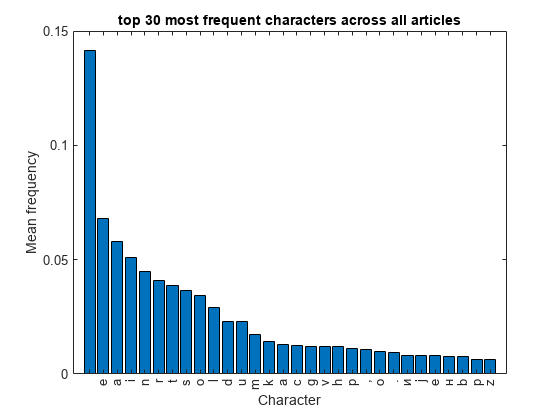

figure;
[sorted_freqs, sorted_indices] = sort(mean(character_freq, 1), 'descend');

sorted_chars = cell(30, 1);
for i = 1:30
    sorted_chars{i} = characterset(sorted_indices(i));
end

bar(1:30, sorted_freqs(1:30));
xticks(1:30)
set(gca,'xticklabel',sorted_chars)

xlabel('Character');
ylabel('Mean frequency');
title('top 30 most frequent characters across all articles');

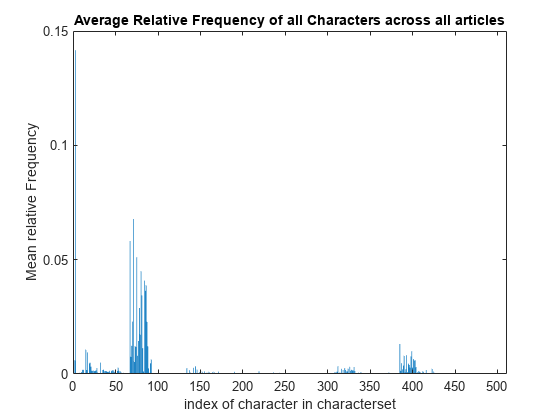


avg_freqs = mean(character_freq, 1);
% Create a bar chart of the average relative frequency of each character
figure
bar(avg_freqs)
title('Average Relative Frequency of all Characters across all articles')
xlabel('index of character in characterset')
ylabel('Mean relative Frequency')

### Part 2: SVD...(70%)

#### Part 2.1: ...of the whole data set (30%)

Now it is time to use the [SVD](https://se.mathworks.com/help/matlab/ref/double.svd.html). You can use the built-in function in Matlab, no need to do the decomposition manually. 

2.1.1) Perform the SVD.

[U,S,V] = svd(character_freq)

U =   -0.128099837223281  -0.017259183238445  -0.004255776502402   0.055542830425549  -0.058851473129696   0.037014916265617  -0.132095773713643   0.044341329672110  -0.052223747811233   0.052106112836177  -0.149719362673375   0.060350197972776  -0.030282885267149   0.124054971637938  -0.201448121202113  -0.056042703001689   0.088850739488802   0.118597728912516   0.010425590381625  -0.006759367221996   0.145232345016597  -0.011553087865323   0.218485237026990  -0.132496078973607   0.134597386931857  -0.108509622742234   0.147358688920908  -0.304967790711761   0.134715925295652  -0.111952521624559   0.110051381654539  -0.157503028470032   0.044133960170031   0.014016158210508  -0.080963433493827   0.149976162567939   0.066740119706241   0.066024361191756   0.131083279143649  -0.086967122716023  -0.102208601949385  -0.134734104743076   0.090467153416952   0.096978275219449   0.005064049303265   0.092617034750367   0.030974420680284   0.209246886980744  -0.059460252061141  -0.17407866775

S =    1.904789061364327                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                   0                

V =   -0.001423632822881   0.002132156065087  -0.001587903997129  -0.000669158379375  -0.001926069114779  -0.002865083252438  -0.000079290456051  -0.000350540858994   0.006042021171225   0.008284489364811  -0.001036342890778  -0.005644255186156  -0.004045146649382   0.008355851311979   0.017643441306964   0.011743289630641   0.003225639053419   0.006420415773861  -0.008849315806928  -0.000749983964995  -0.003156695466311   0.002082545468415  -0.005426431885831  -0.023734673452963  -0.043423303175777   0.002505882239691  -0.015894874414647   0.003728770129073  -0.037172291575228  -0.016042866301273   0.022597291535975  -0.020964794428413  -0.052766183010094   0.041714438835377  -0.035391655416202   0.059718639680917   0.044826817060371   0.043662751579909   0.061179274697605   0.074993615068865   0.035489306650165  -0.039270045972602  -0.101430028268859  -0.061638692518184  -0.056921190969577  -0.033733615673466  -0.014366126634741  -0.016732804288833  -0.047976991076856   0.00626276946

2.1.2) To begin, you should consider the singular values. Plot these in decreasing order (i.e., plot the largest singular value at x=1, the n'th largest at x=n). Give the visualization a proper title and axis labels. 

**Q: **What do the singular values encode? How many degrees of magnitude is there between the biggest and the smallest value? What can you learn from the plot? 

**Answer: **

**What do the singular values encode?**

- **The singular values are sorted in descending order so the first few singular values capture most of the variance in the data. The singular values represent the relative amount of variation in the data that is captured by each component.**

**How many degrees of magnitude is there between the biggest and smallest value?**

- **The biggest value has a value of 1.90479 while the smallest value is 0.00161, this makes the biggest value 1183.1 times larger than the smallest value**

- **We can also see that the largest singular value is about twice as big as the next-big one**

**What can you learn from the plot?**

- **The largest singular values are much bigger than the smaler ones, this means that there is a strong lower dimensional structure to the data, so we might be able to summarixe the data using a lower dimensional subspace.**

- **We also look at the contained energies, where the more coomponents we include the closer we get to 1=100%. And can see that 78% of the data is presented by the first principal component itself! Then 89% for 2 component and 93% for 3 component.**

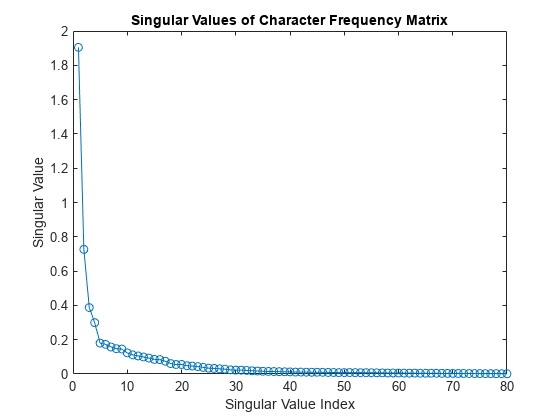

%% s is the singular values. we have 80 singular values.
figure;
plot(diag(S), 'o-')
title('Singular Values of Character Frequency Matrix');
xlabel('Singular Value Index');
ylabel('Singular Value');

%%%%%%%%energies

d = diag(S)

d =    1.904789061364327
   0.726554613759424
   0.387291611455971
   0.299413037501607
   0.179975697167926
   0.172923135780076
   0.157402058913409
   0.147467489292171
   0.145345165029562
   0.123004104676015


eall = d.'*d; % complete Frobenius norm

e = d(1)*d(1)/eall; 
for i = 2:80
    e = [e d(1:i).'*d(1:i)/eall];
end
e

e =    0.783641531526744   0.897656060632680   0.930052691607147   0.949415354404048   0.956411380118204   0.962869853481876   0.968220970962378   0.972917924243375   0.977480655047621   0.980748510788055   0.983432931134728   0.985828604484293   0.987962274097177   0.989821613488070   0.991388064958856   0.992914030604108   0.994129346323932   0.994925900714166   0.995592016914937   0.996253987284447   0.996755474088725   0.997220189192418   0.997622901847931   0.997944647429395   0.998192259064886   0.998422757103935   0.998620967012492   0.998795930327674   0.998922954036254   0.999031714915770   0.999139878983219   0.999232495023038   0.999308402710076   0.999372645707501   0.999428435332587   0.999475828518792   0.999520331655416   0.999560113438152   0.999596873954143   0.999629395138193   0.999656702127761   0.999683119754592   0.999707675346216   0.999730307506828   0.999751992415401   0.999772868376849   0.999791144677100   0.999807823663210   0.999822716595445   0.99983735247

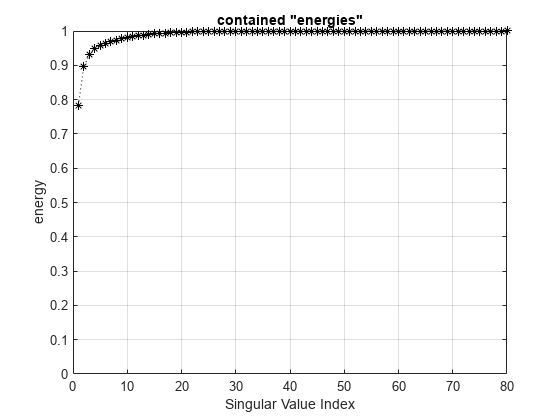

%% We look at the energies and can see that 78% of the data is presented by the first principal component itself! Then 89% for 2 component and 93% for 3 component.
figure; 
plot(e, 'k:'), grid on, hold on, plot(e, 'k*') 
plot([1 1], [0 0], 'k')% make sure that 0 is in the plot, too
title('contained "energies"')
xlabel('Singular Value Index');
ylabel('energy');

2.1.3) Next perform a rank-2, then a rank-3, approximation. Visualize the approximated data in **V**-coordinates. 

**Q: **Is there a clear structure in your data, and if yes describe it? (Can you, for example, distinguish groups?) Do you prefer the rank-2 or the rank-3 approximation, and why?

**Answer: We can see three clear grouings one big with the majority of the datapoints, one less big and one very small group with only 4 data points. Given that we have looked at the energies and now at visuializations we can see that there is a small difference between rank 2 and rank 3 approximation (89% vs 93%). It will not make that big of a dfference, but since rank 3 approximation seems to have the data points a bit more spread in 3d making it easier to differentiate between points i would choose rank 3 as my preference.**

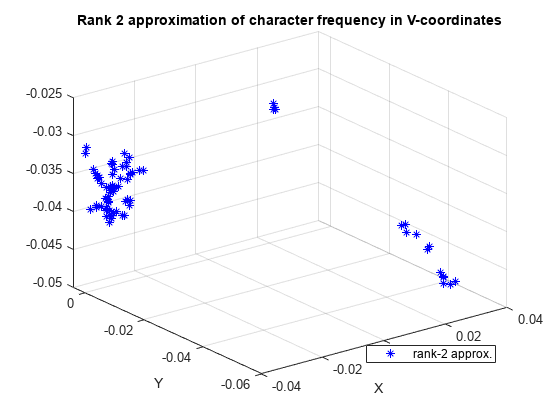

DinV = U * S; 

%RANK 1
D1 = U(:,1) * S(1,1) * V(:,1)';
D1inV = U(:,1) * S(1,1);

%RANK 2
D2 = U(:,1:2) * S(1:2,1:2) * V(:,1:2)';
%D2inV = U(:,1:2) * S(1:2,1:2);
D2inV = D2*V';

%RANK 3
D3 = U(:,1:3) * S(1:3,1:3) * V(:,1:3)';
%D3inV = U(:,1:3) * S(1:3,1:3);
D3inV = D3 * V';

DinV_tit = [article_title'; num2cell(DinV)']';

figure;
format long,  
scatter3(D2inV(:,1), D2inV(:,2), D2inV(:,3),  'b*'), grid on,
legend({'rank-2 approx.'},"Location","southeast")
title('Rank 2 approximation of character frequency in V-coordinates');
xlabel('X');
ylabel('Y');

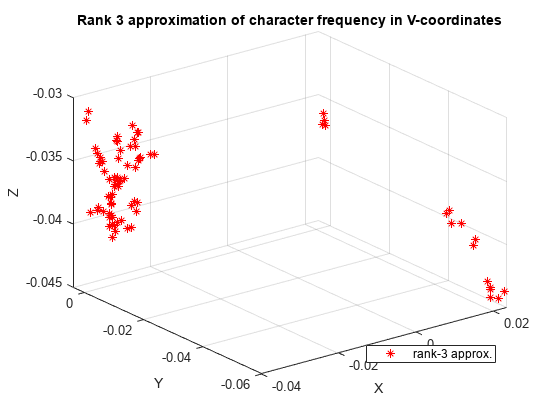

%%VISUALIZE RANK 3
figure;
scatter3(D3inV(:,1), D3inV(:,2), D3inV(:,3), 'r*')
title('Rank 3 approximation of character frequency in V-coordinates');
xlabel('X');
ylabel('Y');
zlabel('Z');
legend({'rank-3 approx.'},"Location","southeast")

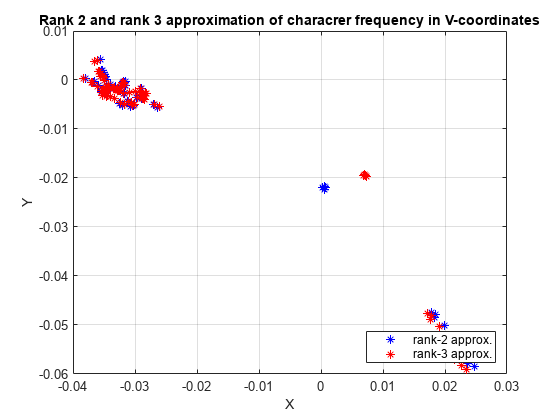

%%VISUALIZE BOTH RANK 2 AND RANK 3 in 2d
figure; 
plot (D2inV(:,1), D2inV(:,2), 'b*'), hold on, grid on,
plot(D3inV(:,1), D3inV(:,2), 'r*'),
legend({'rank-2 approx.','rank-3 approx.'},"Location","southeast")
title('Rank 2 and rank 3 approximation of characrer frequency in V-coordinates')
xlabel('X');
ylabel('Y');
zlabel('Z');

2.1.4) To understand the structure that can be seen, add labels to the points in your preferred approximation (rank-2 or rank-3) (hint: [add text to plots](https://se.mathworks.com/help/matlab/ref/text.html)). You do not have to label all points as this can result in a very busy plot (however, if you prefer, you can of course label all points). You can, for example, label only the countries (or only the capitals), or label only a certain number of points. What is important is that you should get an idea of how the structure in the data can be explained.

**Q: **How would you explain the structure you see in the data, based on the information from the labels?

**Answer: **

**We label all points even tough this creates a busy plot we can explore the data toroughly with matlabs interactive tools like zoom and pan. What we notice is that we can see the same pattern as we saw in the barchart where we have 3 groups, where the biggest group is contries that use latin characters, and then contries that cyrillic characrters, and lastly the small cluster with 4 data points are contries that use greek characters (Greece and Cyprus). We also see that contries and their respective capitals are plotted close together this makes sense as the wikipedia articles for contry and city is written with the same characters.**

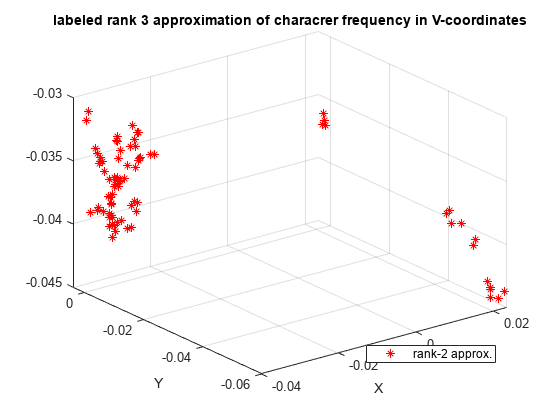

figure;
format long
scatter3(D3inV(:,1), D3inV(:,2), D3inV(:,3), 'r*'), grid on;
for i = 1:size(D3inV, 1)
    text(D3inV(i, 1), D3inV(i, 2), article_title{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
title('labeled rank 3 approximation of characrer frequency in V-coordinates')
legend({'rank-2 approx.'},"Location","southeast")
xlabel('X');
ylabel('Y');

#### Part 2.2: ...of subsets (40%)

From part 2.1 you learned that the data contains clearly distinguishable groups, however, it was difficult to observe the structure of these individual groups. You will therefore perform a new SVD analysis of each of these groups seperatly. Separating out the groups can be done simply in the **V**-coordinate space of the previous SVD (hint: find a values along one of the axes that separates the groups). 

2.2.1) Separate out the groups by the logic described above. Make sure that all points are included in a group by comparing the sum the number of points in each group to the total (80).

**Q: **What were the thresholds you used to separate the groups and along which axis?

**Answer: From the figure we see three groups where we can easily split the groups once on the x axis with a value of -0.01 so that we get the data split into two, one containign the big group and the other containing the two smaller groups. We then split the two smaller groups on the x-axis with a value of 0.01 and are now left with the three groups that we want. We check the lenghts of the groups and sum them to 80 to see that we have included all data pints aswell as visualize it to make sure.**

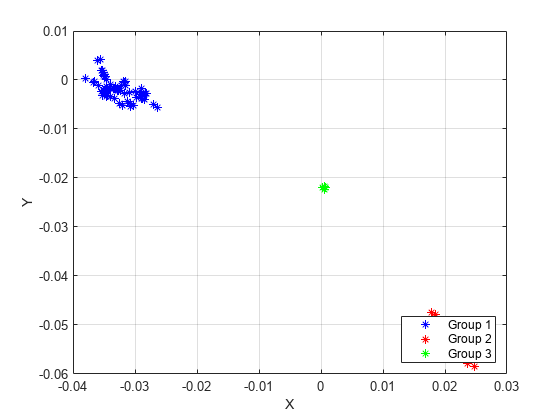

% First we split into two groups on x-axis -0.18

Group1 = D2inV(D2inV(:,1) < -0.01, :);
tmp = D2inV(D2inV(:,1) > -0.01, :);

% Then we split the group to the right by y-axis 0.1 so we are left with 3 groups
Group2 = tmp(tmp(:,1) > 0.01, :);
Group3 = tmp(tmp(:,1) < 0.01, :);

% CHECK if we include all points
assert(size(Group1,1) + size(Group2,1) + size(Group3,1) == size(character_freq, 1));

% We visualize to see if we have managed to split the 3 groups
figure;
plot (Group1(:,1), Group1(:,2), 'b*'),hold on, grid on
plot (Group2(:,1), Group2(:,2), 'r*');
plot (Group3(:,1), Group3(:,2), 'g*');
legend({'Group 1', 'Group 2', 'Group 3'},"Location","southeast")
xlabel('X');
ylabel('Y');

2.2.2) Next, do the following steps for each of the groups (note that you should answer the questions even though they are not marked explicitly with a "**Q**"):

a) Perform SVD

b) Plot the singular values (with title, axis label,..), what does this tell you?

c) Visualize a rank-2 (and rank-3) approximation of the data in **V**-coordinates and standard coordinates, including the "usual" (title, axis label,..) as well as labels for the points. Which of the plots do you prefer and why? What can you see in these plots? Are there any surprises/interesting aspects/confusing aspects? Present your insights by inserting images of interesting finds in your plots (f.ex. after zooming in on an area, rotating the 3d view, adding additional labels, etc..) (insert images by going to the **INSERT **tab and clicking "Image"), and explaining what can be seen in the images and why you find this interesting. 

**ANWSERS:**

**Plot the singular values (with title, axis label,..), what does this tell you?**

**The resulting plot will show the importance of each singular value. The decay of the singular values will give an indication of how much of the variance in the data is explained by each singular value. We can usualy see that the first singular value is much bigger than the rest, meaning this value explains most of the data.**

**Which of the plots do you prefer and why? **

- **For 3d visualization I preffer the plots in standard because we get a bigger spread making it easier to analyse the data points and see how they relate to eachother, in V-coordinates, the 3d visualization does not do much since they all look to be in a similar z range.**

**What can you see in these plots? **

- **We can get a closer look of the different groups and see similarities and differences in their relative character frequency between different contries and capitals, are the data points plotted closer together then they have similarities are they plotted futher away then we have less similarities**

**For group 1, I found a couple of interesting things:**

- **Is that iceland and reyjavik is so closely plotted to eastern european locations like Latvia and hungary. I had the impression that Iceland would maybe relate more to scandinavian locations given the roots of iceland as a settlement made of mostly Vikings.**

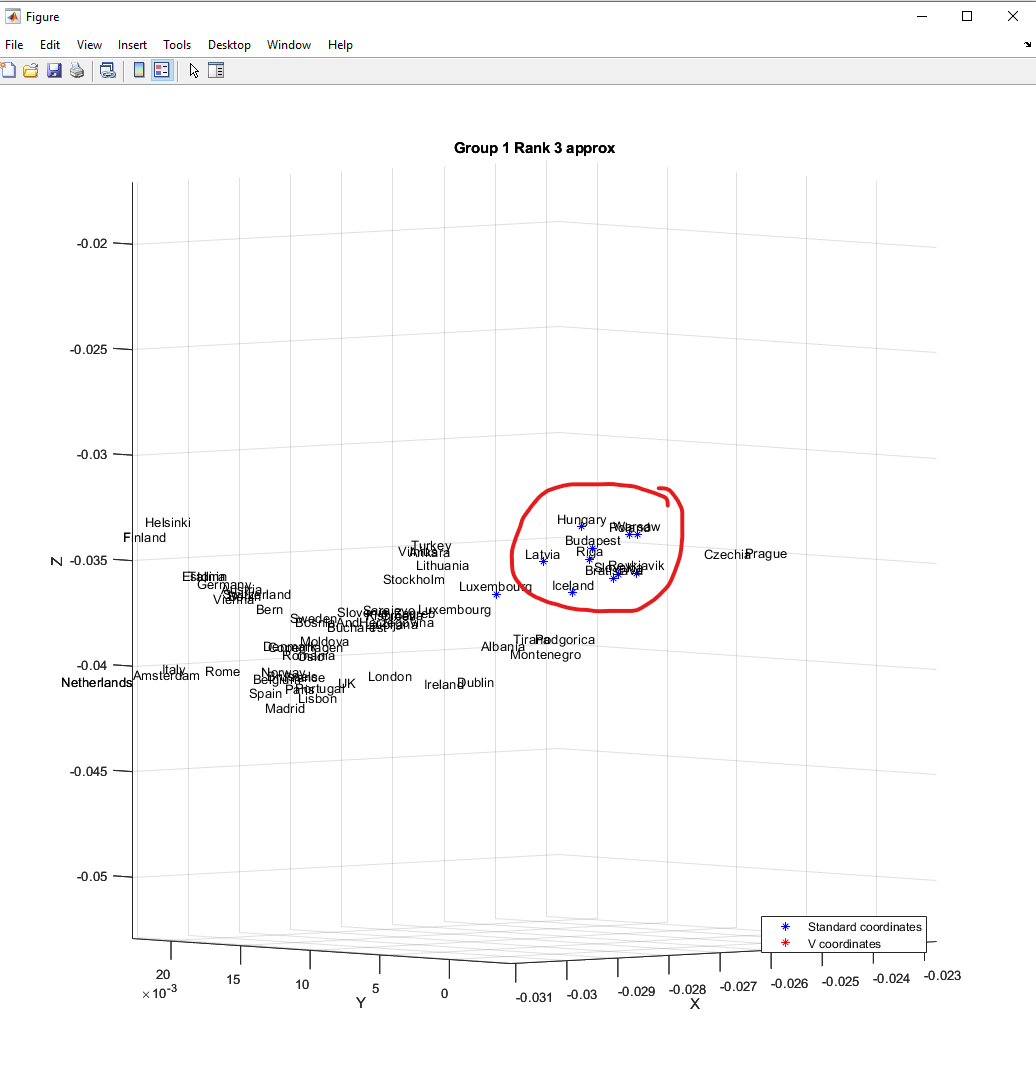

- **Another similar thing we can see is that Turkey is so closely related to Lithuania, this is suprising because the difference in geo location is quite big, it is also a bit interesting that Lithuania is not plotted closer to other eastern european countries.**

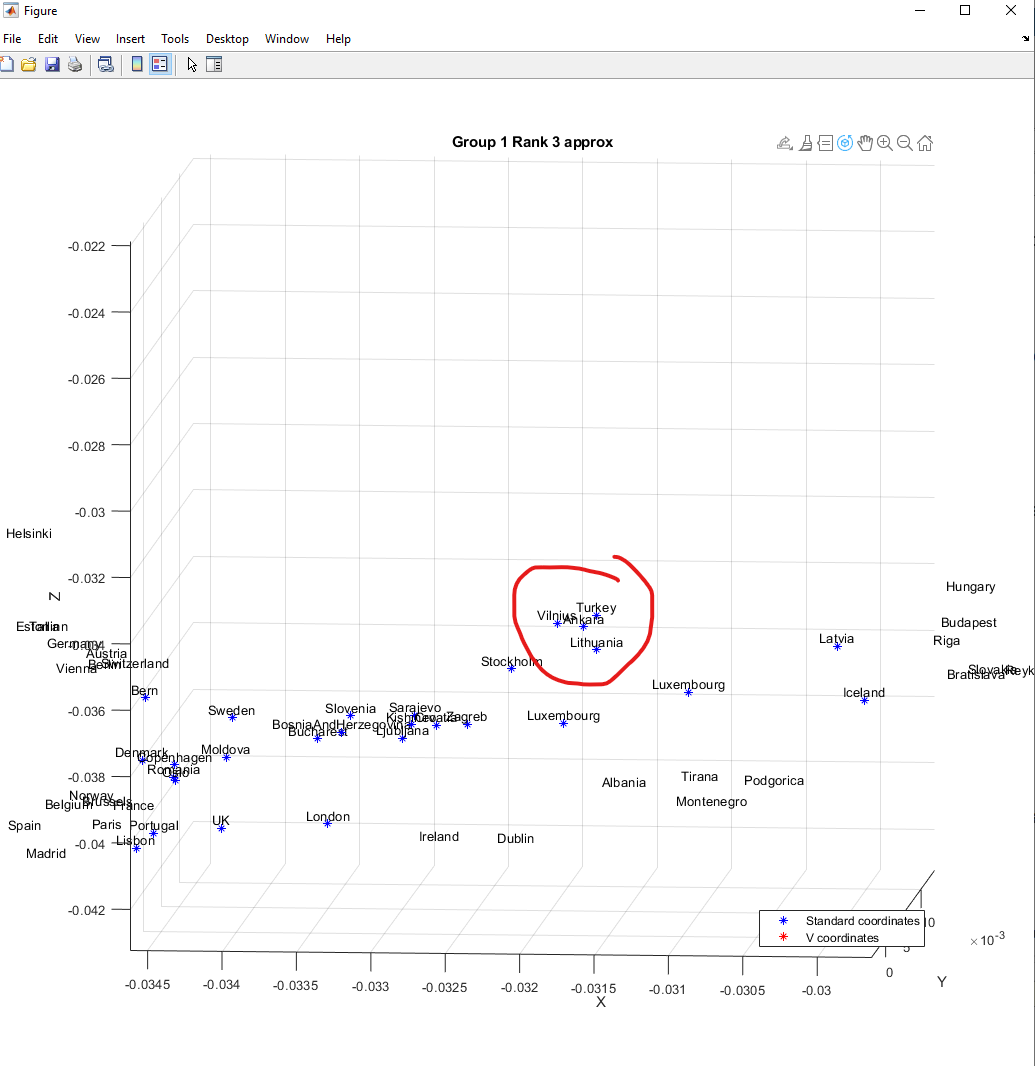

- **Cool to see that Norway, Denmark and Sweeden are relatively close (even tough Norway seems to be quite closer to Belgium and france) and that Finnland is plotted quite a distance away from its scandinavian neighbours.**

- 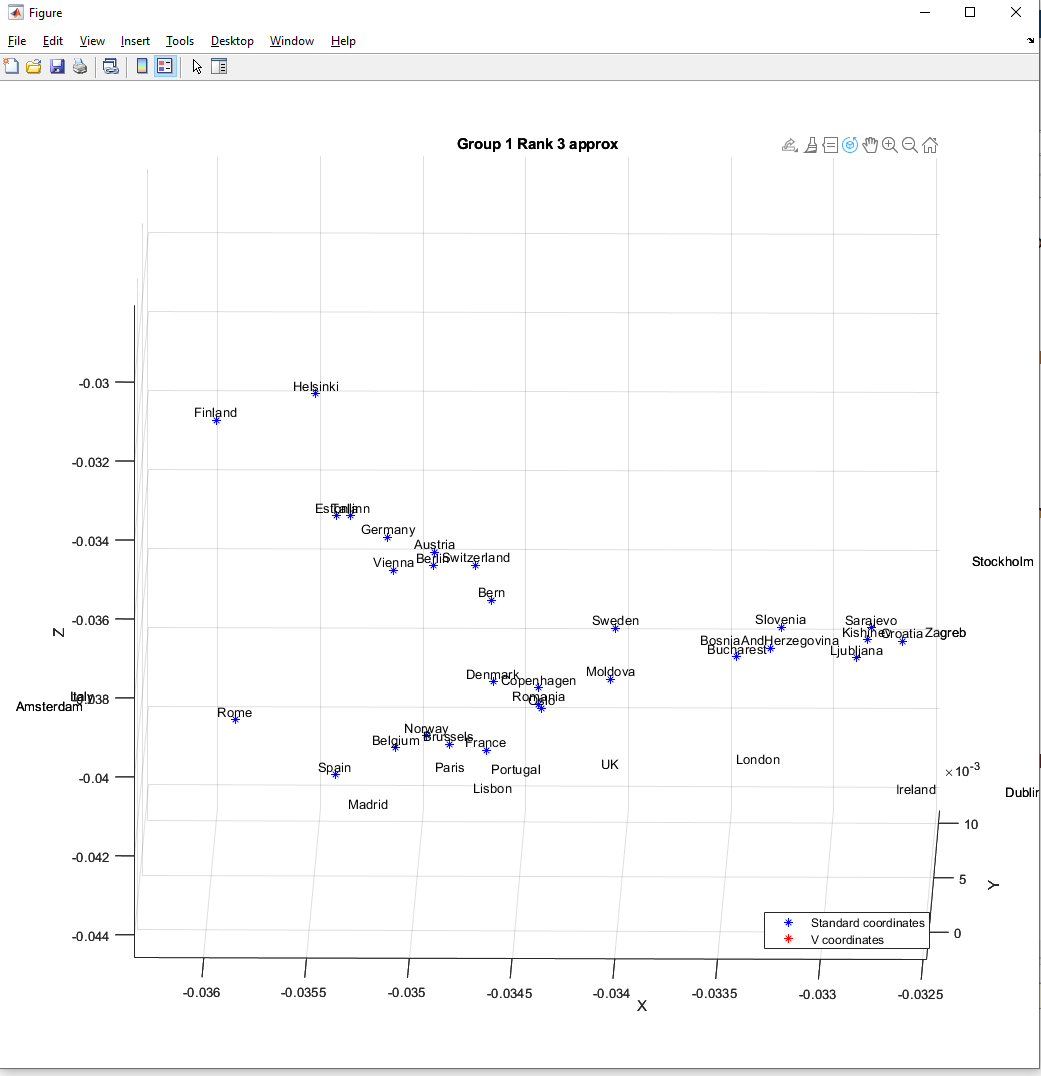

**For group 2: (serbia in this group cool, balkans seem to be in group 1 and group 2) (Cool to see that the way the points are plotted is similar in order to their geo location**

- **What i found interesting about group 2 is that the data points are plotted in a way that resembles the real world location. With the balkans being more grouped towards the bottom, with russa in the middle and Ukraine and Belarus at the top. This is very similar to their geo location. One other suprising thing is that moldova is not part of this group.**

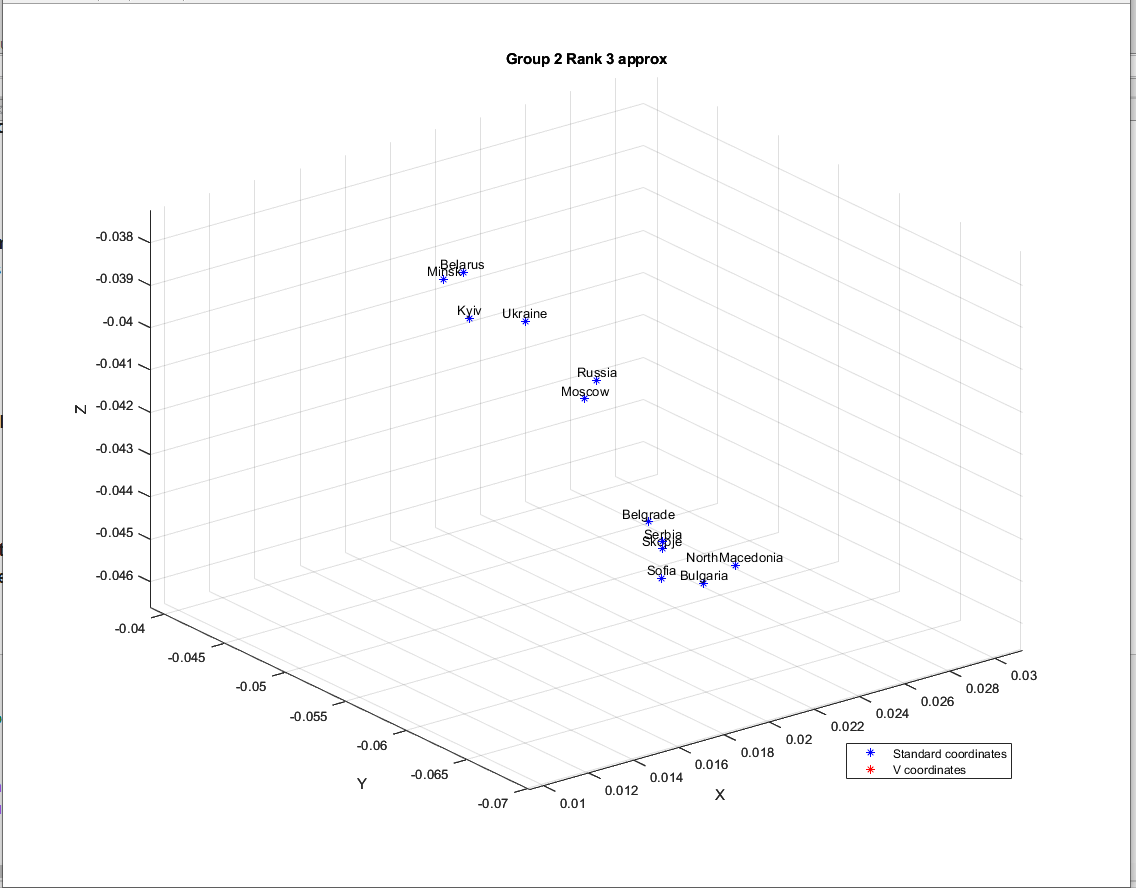

- **Another interesting thing is that the balkans seems to be splitted among group 1 and group 2 so we can see that their characters are pretty different to each other. In group 2 we can see Serbia, North Macedonia and Bulgaria. So i would assume that those countries use cyrillic characters while the rest of the balkans use more Latin like characters.**

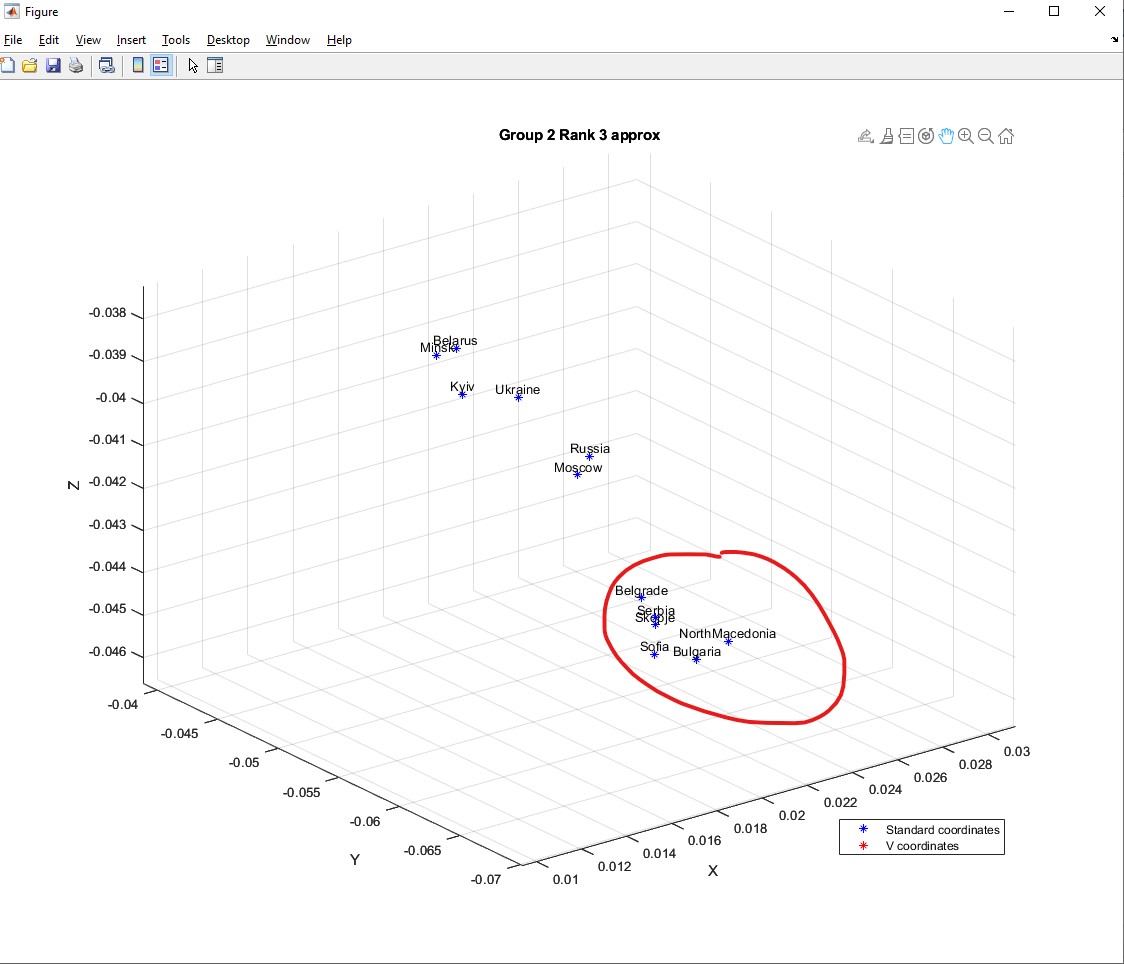

**For Group 3:**

- **For Group 3, it was not really that interesting, not a big difference in rank 2 or 3, approx. An interesting fact, though, is that there is such a small group in the data set since the Greek characters are so unique to Greece and Cyprus.**

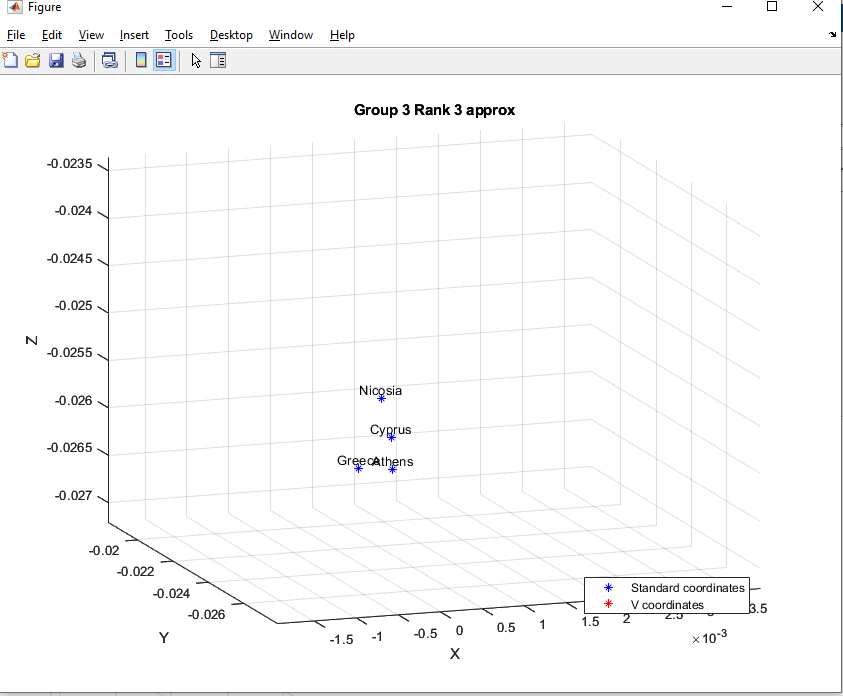

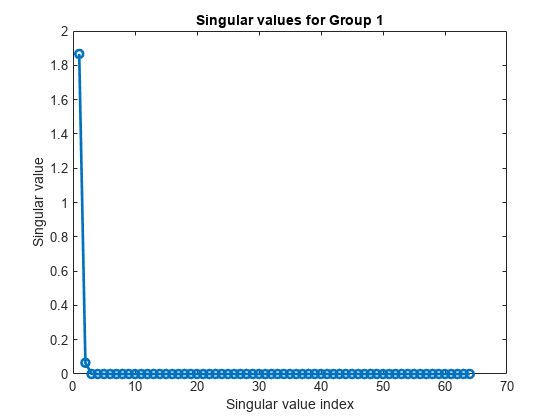

% a) / % b)

% SVD and visualization for Group 1
[U1, S1, V1] = svd(Group1);
figure;
plot(diag(S1), 'o-', 'LineWidth', 2);
title('Singular values for Group 1');
xlabel('Singular value index');
ylabel('Singular value');

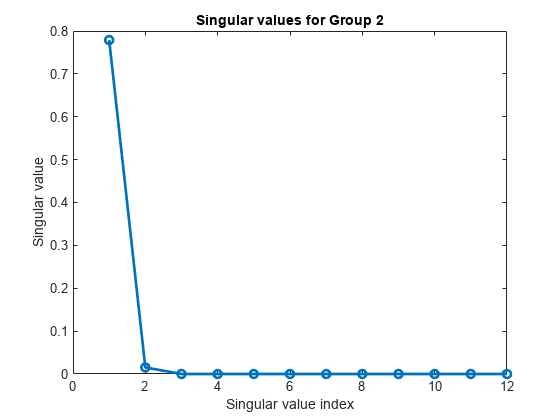

% SVD and visualization for Group 2
[U2, S2, V2] = svd(Group2);
figure;
plot(diag(S2), 'o-', 'LineWidth', 2);
title('Singular values for Group 2');
xlabel('Singular value index');
ylabel('Singular value');

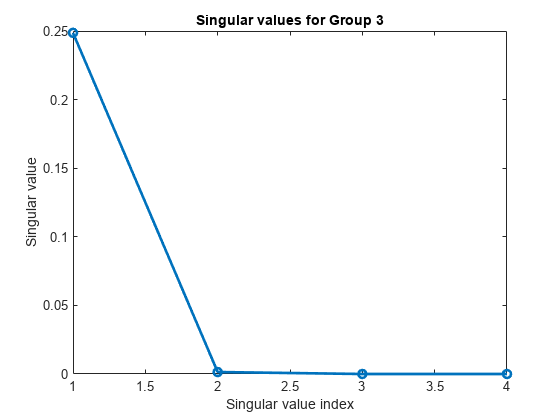


% SVD and visualization for Group 3
[U3, S3, V3] = svd(Group3);
figure;
plot(diag(S3), 'o-', 'LineWidth', 2);
title('Singular values for Group 3');
xlabel('Singular value index');
ylabel('Singular value');


% c)
%%%%%%%%%%%%%%%%%%%%GROUP1%%%%%%%%%%%%%%%%%%%%%%%
%Group1 Rank 2
G1R2 = U1(:,1:2) * S1(1:2,1:2) * V1(:,1:2)';
G1R2V = G1R2 * V1'

G1R2V =   -0.037748325862233   0.036180716513439   0.001642326876893  -0.008879960761996   0.035630077492379   0.084503272894562   0.011355654293651  -0.048784868529448  -0.009526387783201   0.000819656124856  -0.006529506316583   0.036589593106937  -0.020707794091336   0.068622863337456  -0.037423611765330  -0.017377874317406   0.018365308718784  -0.029870792926472   0.015268518242843   0.012424044574438  -0.004003861830090  -0.031439420820915   0.016739613511884  -0.006851274936669  -0.019401135739667  -0.017614270815009  -0.045715305305545  -0.017733366849189  -0.015461632136148  -0.018517824860917   0.016102980153167  -0.013056371916506  -0.002200953742630  -0.007045942646270   0.038447091720002  -0.000614223191240   0.007841476243937  -0.020602839083657   0.024379947209934   0.010058621255426   0.030924407689371   0.040754061004156  -0.022917147629109  -0.008854425114782  -0.019650018243698  -0.034121144969105   0.020362595604202  -0.030234162488891  -0.012426242998232   0.0246543

%G1R2V = U1(:,1:2) * S1(1:2,1:2);




%Group1 RANK 3
G1R3 = U1(:,1:3) * S1(1:3,1:3) * V1(:,1:3)';
G1R3V = G1R3 * V1'

G1R3V =   -0.037748325862233   0.036180716513439   0.001642326876893  -0.008879960761996   0.035630077492379   0.084503272894562   0.011355654293651  -0.048784868529448  -0.009526387783201   0.000819656124856  -0.006529506316583   0.036589593106937  -0.020707794091336   0.068622863337456  -0.037423611765330  -0.017377874317406   0.018365308718784  -0.029870792926472   0.015268518242843   0.012424044574438  -0.004003861830090  -0.031439420820915   0.016739613511884  -0.006851274936669  -0.019401135739667  -0.017614270815009  -0.045715305305545  -0.017733366849189  -0.015461632136148  -0.018517824860917   0.016102980153167  -0.013056371916505  -0.002200953742630  -0.007045942646270   0.038447091720002  -0.000614223191240   0.007841476243937  -0.020602839083657   0.024379947209934   0.010058621255426   0.030924407689371   0.040754061004156  -0.022917147629109  -0.008854425114782  -0.019650018243698  -0.034121144969105   0.020362595604202  -0.030234162488891  -0.012426242998232   0.0246543

%G1R3V = U1(:,1:3) * S1(1:3,1:3);

%%%%%%%%%%%%%%%%%%%%GROUP2%%%%%%%%%%%%%%%%%%%%%%%
%Group2 Rank 2
G2R2 = U2(:,1:2) * S2(1:2,1:2) * V2(:,1:2)';
%G2R2V = U2(:,1:2) * S2(1:2,1:2);
G2R2V = G2R2 * V1'

G2R2V =   -0.031187961759876   0.027533120690085  -0.026194855510301  -0.007711717043694   0.037736005532258   0.038732121429516   0.001846435781205  -0.037737356333651   0.004269379863660   0.026472197758430  -0.006090262740120  -0.034402442558838  -0.010899182134195   0.018950903534426  -0.029708370534955   0.007619869505345   0.013831032672956   0.017249730842530  -0.001658829586223   0.027696599952046   0.003000024398475  -0.022860271698208   0.016762247916588   0.005282836118577  -0.012053153276409  -0.006118735411890  -0.024403163012241  -0.013872275432200  -0.008241058116743  -0.001015719320458  -0.012386633085560  -0.013318964586751   0.008785446269619  -0.002596091179537   0.004762189551614  -0.014564217933627  -0.024328429833368   0.016837651567323   0.023446789194879   0.002193100388318   0.010508387942586   0.020621951812014  -0.010614803896464  -0.002435478494493  -0.028402824169367  -0.033417818541290   0.003730618183392  -0.016462149052093  -0.028885606825986  -0.0007887

%Group2 RANK 3
G2R3 = U2(:,1:3) * S2(1:3,1:3) * V2(:,1:3)';
%G2R3V = U2(:,1:3) * S2(1:3,1:3);
G2R3V = G2R3 * V1'

G2R3V =   -0.031187961759876   0.027533120690085  -0.026194855510301  -0.007711717043694   0.037736005532258   0.038732121429516   0.001846435781205  -0.037737356333651   0.004269379863660   0.026472197758430  -0.006090262740120  -0.034402442558838  -0.010899182134195   0.018950903534426  -0.029708370534955   0.007619869505345   0.013831032672956   0.017249730842530  -0.001658829586223   0.027696599952046   0.003000024398475  -0.022860271698208   0.016762247916588   0.005282836118577  -0.012053153276409  -0.006118735411890  -0.024403163012241  -0.013872275432200  -0.008241058116743  -0.001015719320458  -0.012386633085560  -0.013318964586752   0.008785446269619  -0.002596091179537   0.004762189551614  -0.014564217933627  -0.024328429833368   0.016837651567323   0.023446789194879   0.002193100388318   0.010508387942586   0.020621951812014  -0.010614803896464  -0.002435478494493  -0.028402824169367  -0.033417818541290   0.003730618183392  -0.016462149052093  -0.028885606825986  -0.0007887

%%%%%%%%%%%%%%%%%%%%GROUP3%%%%%%%%%%%%%%%%%%%%%%%
%Group3 Rank 2
G3R2 = U3(:,1:2) * S3(1:2,1:2) * V3(:,1:2)';
%G3R2V = U3(:,1:2) * S3(1:2,1:2);
G3R2V = G3R2 * V1'

G3R2V =   -0.021757570138140   0.019895478895617  -0.010245457388121  -0.005270618706586   0.023907519225766   0.036079021338471   0.003484080862102  -0.027075255700556  -0.000559295634489   0.010950873864210  -0.004046049253284  -0.005165530999038  -0.009413135499759   0.024220082901020  -0.021078351723063  -0.001088608322505   0.010040127298903  -0.000184601272362   0.003002245756987   0.014242158361847   0.000254687290141  -0.016855746238262   0.010839437622722   0.000496458721851  -0.009567306365322  -0.006726417243799  -0.020919604885471  -0.009904732665733  -0.007070270877112  -0.004871013492221  -0.001154692858933  -0.008553919228622   0.003038913889630  -0.002750986363190   0.011191135175673  -0.006064155988969  -0.007994752142996   0.001879384899136   0.015394340786686   0.003312625246291   0.011714170319912   0.018189117655540  -0.009829546148023  -0.003121158084263  -0.016268788160881  -0.021790090946213   0.006418011822688  -0.013966520435257  -0.014725685798669   0.0056154

%Group3 RANK 3
G3R3 = U3(:,1:3) * S3(1:3,1:3) * V3(:,1:3)';
%G3R3V = U3(:,1:3) * S3(1:3,1:3);
G3R3V = G3R3 * V1'

G3R3V =   -0.021757570138140   0.019895478895617  -0.010245457388121  -0.005270618706586   0.023907519225766   0.036079021338471   0.003484080862102  -0.027075255700556  -0.000559295634489   0.010950873864210  -0.004046049253284  -0.005165530999038  -0.009413135499759   0.024220082901020  -0.021078351723063  -0.001088608322505   0.010040127298903  -0.000184601272362   0.003002245756987   0.014242158361847   0.000254687290141  -0.016855746238262   0.010839437622722   0.000496458721851  -0.009567306365322  -0.006726417243799  -0.020919604885471  -0.009904732665733  -0.007070270877112  -0.004871013492221  -0.001154692858933  -0.008553919228622   0.003038913889630  -0.002750986363190   0.011191135175673  -0.006064155988969  -0.007994752142996   0.001879384899136   0.015394340786686   0.003312625246291   0.011714170319911   0.018189117655540  -0.009829546148023  -0.003121158084263  -0.016268788160881  -0.021790090946213   0.006418011822688  -0.013966520435257  -0.014725685798669   0.0056154



%%%CODE FOR GETTING NAMES IN PLOT

Group1_tit = {};
Group2_tit = {};
Group3_tit = {};

for i = 1:size(D2inV, 1)
    %%%%
    if D2inV(i, 1) < -0.01
      Group1_tit = [Group1_tit, article_title{i}];
    elseif D2inV(i, 1) > -0.01
        
        if D2inV(i, 1) > 0.01
        Group2_tit = [Group2_tit, article_title{i}];
        else
            Group3_tit = [Group3_tit, article_title{i}];
        end

    end
end


%%Tanspose so its more like a list
Group1_tit = Group1_tit'

Group1_tit = 64×1 cell array
    {'London'    }
    {'Madrid'    }
    {'Oslo'      }
    {'Berlin'    }
    {'Paris'     }
    {'Ankara'    }
    {'Rome'      }
    {'Vienna'    }
    {'Stockholm' }
    {'Warsaw'    }
    {'Helsinki'  }
    {'Tallinn'   }
    {'Lisbon'    }
    {'Bucharest' }
    {'Amsterdam' }
    {'Brussels'  }
    {'Prague'    }
    {'Budapest'  }
    {'Bern'      }
    {'Copenhagen'}
    {'Bratislava'}
    {'Dublin'    }
    {'Zagreb'    }
    {'Sarajevo'  }
    {'Kishinev'  }
    {'Tirana'    }
    {'Vilnius'   }
    {'Ljubljana' }
    {'Riga'      }
    {'Luxembourg'}


Group2_tit = Group2_tit'

Group2_tit = 12×1 cell array
    {'Moscow'        }
    {'Belgrade'      }
    {'Kyiv'          }
    {'Minsk'         }
    {'Sofia'         }
    {'Skopje'        }
    {'Russia'        }
    {'Serbia'        }
    {'Ukraine'       }
    {'Belarus'       }
    {'Bulgaria'      }
    {'NorthMacedonia'}


Group3_tit = Group3_tit'

Group3_tit = 4×1 cell array
    {'Athens' }
    {'Nicosia'}
    {'Greece' }
    {'Cyprus' }


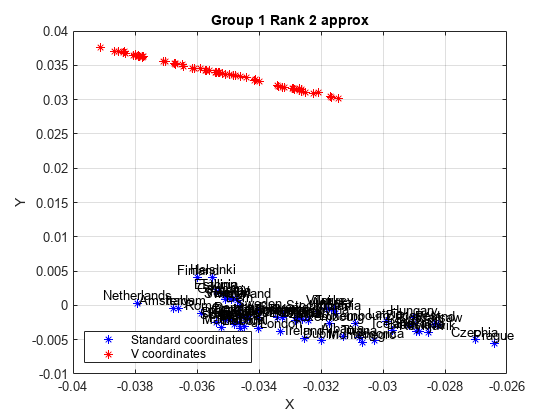

%%%%%%%%%%%%%%%%%%%%GROUP1%%%%%%%%%%%%%%%%%%%%%%%

%Group1 RANK 2 VISUALIZATION
figure
plot (G1R2(:,1), G1R2(:,2), 'b*'),hold on, grid on
for i = 1:size(G1R2, 1)
    text(G1R2(i, 1), G1R2(i, 2), Group1_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
plot (G1R2V(:,1), G1R2V(:,2), 'r*');
title('Group 1 Rank 2 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southwest")
xlabel('X');
ylabel('Y');

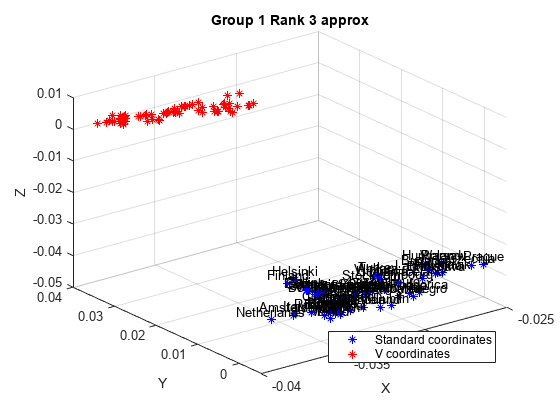

%Group1 RANK 3 VISUALIZATION
figure
scatter3(G1R3(:,1), G1R3(:,2),G1R3(:,3), 'b*'),hold on, grid on
for i = 1:size(G1R3, 1)
    text(G1R3(i, 1), G1R3(i, 2), G1R3(i, 3), Group1_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
scatter3(G1R3V(:,1), G1R3V(:,2), G1R3V(:,3), 'r*');
title('Group 1 Rank 3 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southeast")
xlabel('X');
ylabel('Y');
zlabel('Z');

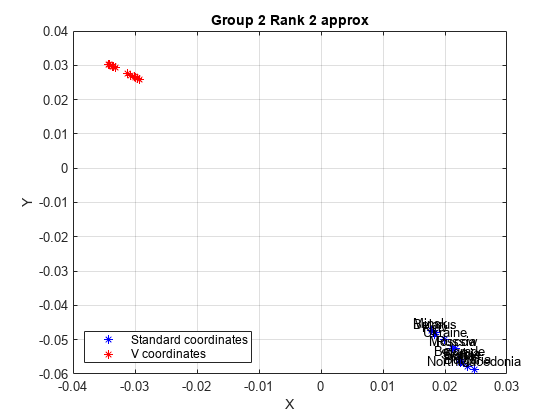

%%%%%%%%%%%%%%%%%%%%GROUP2%%%%%%%%%%%%%%%%%%%%%%%
%Group2 RANK 2 VISUALIZATION
figure
plot (G2R2(:,1), G2R2(:,2), 'b*'),hold on, grid on
for i = 1:size(G2R2, 1)
    text(G2R2(i, 1), G2R2(i, 2), Group2_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
plot (G2R2V(:,1), G2R2V(:,2), 'r*');

title('Group 2 Rank 2 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southwest")
xlabel('X');
ylabel('Y');

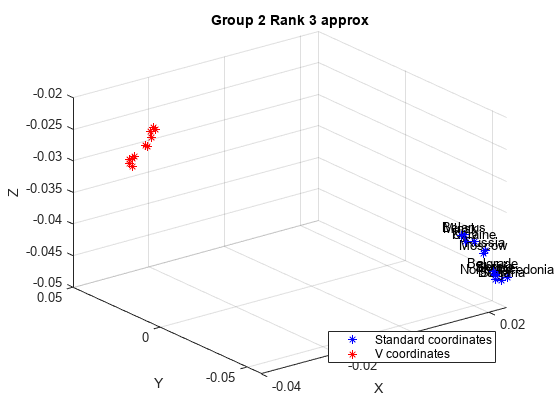

%Group2 RANK 3 VISUALIZATION
figure
scatter3(G2R3(:,1), G2R3(:,2),G2R3(:,3), 'b*'),hold on, grid on
for i = 1:size(G2R3, 1)
    text(G2R3(i, 1), G2R3(i, 2), G2R3(i, 3), Group2_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
scatter3(G2R3V(:,1), G2R3V(:,2), G2R3V(:,3), 'r*');

title('Group 2 Rank 3 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southeast")
xlabel('X');
ylabel('Y');
zlabel('Z');

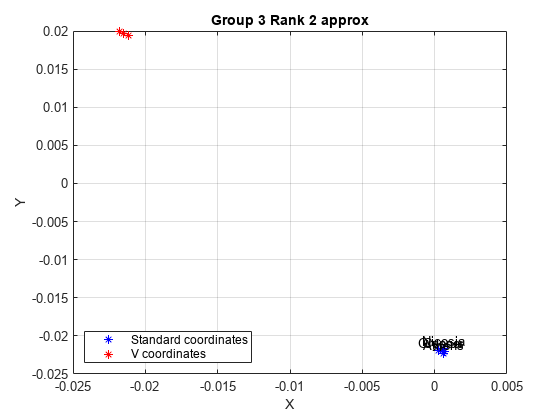

%%%%%%%%%%%%%%%%%%%%GROUP3%%%%%%%%%%%%%%%%%%%%%%%
figure
plot (G3R2(:,1), G3R2(:,2), 'b*'),hold on, grid on
for i = 1:size(G3R3, 1)
    text(G3R2(i, 1), G3R2(i, 2), Group3_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
plot (G3R2V(:,1), G3R2V(:,2), 'r*');

title('Group 3 Rank 2 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southwest")
xlabel('X');
ylabel('Y');

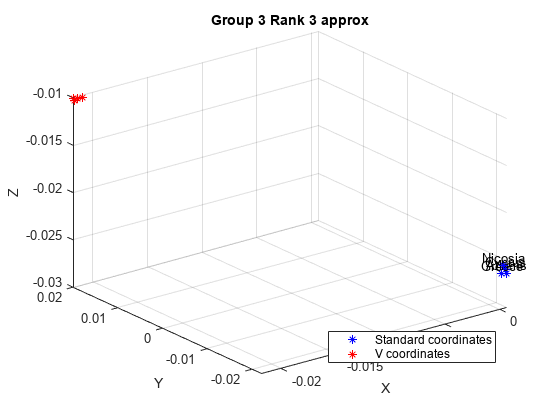

%Group2 RANK 3 VISUALIZATION
figure
scatter3(G3R3(:,1), G3R3(:,2),G3R3(:,3), 'b*'),hold on, grid on
for i = 1:size(G3R3, 1)
    text(G3R3(i, 1), G3R3(i, 2), G3R3(i, 3), Group3_tit{i}, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
end
scatter3(G3R3V(:,1), G3R3V(:,2), G3R3V(:,3), 'r*');

title('Group 3 Rank 3 approx');
legend({'Standard coordinates', 'V coordinates'},"Location","southeast")
xlabel('X');
ylabel('Y');
zlabel('Z');

2.2.3) Now for some final reflections:

**Q: **What have you learned while doing this assignment (about the SVD, about languages, ...)?

**Answer: **

- **Have learned that there is mainly 3 different groups of characters/written languages in europe being latin characters, cyrillic and greek.**

- **Learned that it is possible to use the SVD to get a lot of info with low rank apporximation without a big loss of information.**

- **Learned how to visualize big data with and without low rank approximation, was fun to see that the groupings found before the svd stayed consistent after the svd was perfomed aswell.**

**Q: **For which problems would you apply this method (which problems can be solved using SVD)? What about the type of data, can this method be used for any type of data? Give some examples of both appropriate and - if you think it cannot be used for all types of data - inappropriate data (you do not have to find actual data sets, just come up with realistic scenarios).

**Answer: **

**SVD seems to be usefull for data that has high dimensionality and where we can use a low rank approximation to get meaningfull insights without huge loss of information. Some examples of this include:**

- **SVD can be used on for example image processing, like on for example the MNIST handwritten numbers where the numbers are presented as a matrix, we could use the svd to forexample compress the image.**

- **Since it can be used for image processing it could also work well on signal processing to compress or reduce noise.**

- **Dimensionality reduction and model simplification by eliminating redundant or insignifficant variables or parameters.**

**The SVD would rewqure that the data is represented in matrix form and that the matrix does not have extreme outliers or missing data. Some data that would not fit the svd would be:**

- **Graph data (for example data on airline destination and origin). **

- **Time series data like for example cryprto prices that change hourly or daily.**